addpath("/Users/penquin/Library/CloudStorage/OneDrive-KMITL/Project/function");
EmiPMs = ipOpa("/Users/penquin/Library/CloudStorage/OneDrive-KMITL/Project/DataBase/EmiPMs copy2.xlsx", "Opacity", [3, Inf])

EmiPMs = 16×6 table
    Condition1    VarName7      B7      B7CeO2_300DOCPt_300PDPF      B10      B100 
    __________    ________    ______    _______________________    _______    _____

       1500          84         9.99              ""                2.3922      0.9
       1500         112        9.045              ""                2.6529      4.3
       1500         140       16.875              ""                5.5842     8.45
       1500         160       25.245              ""                 8.571    11.95
       2000          84         4.59              ""               0.73846      0.9
       2000         112        5.805              ""                1.0324      0.7
       2000         140         8.64              ""                2.0049     2.05
       2000        

EmiPMs = removevars(EmiPMs, ["B7CeO2_300DOCPt_300PDPF" "B10"]);
EmiPMs(13 : end, :) = [];
EmiPMs.Properties.VariableNames = ["RPM" "Torque" "B7" "B100"] 

EmiPMs = 12×4 table
    RPM     Torque      B7      B100 
    ____    ______    ______    _____

    1500      84        9.99      0.9
    1500     112       9.045      4.3
    1500     140      16.875     8.45
    1500     160      25.245    11.95
    2000      84        4.59      0.9
    2000     112       5.805      0.7
    2000     140        8.64     2.05
    2000     160      12.825      3.1
    2500      84       3.375        1
    2500     112        6.21     0.65
    2500     140        6.48      1.2
    2500     160        9.18     2.15


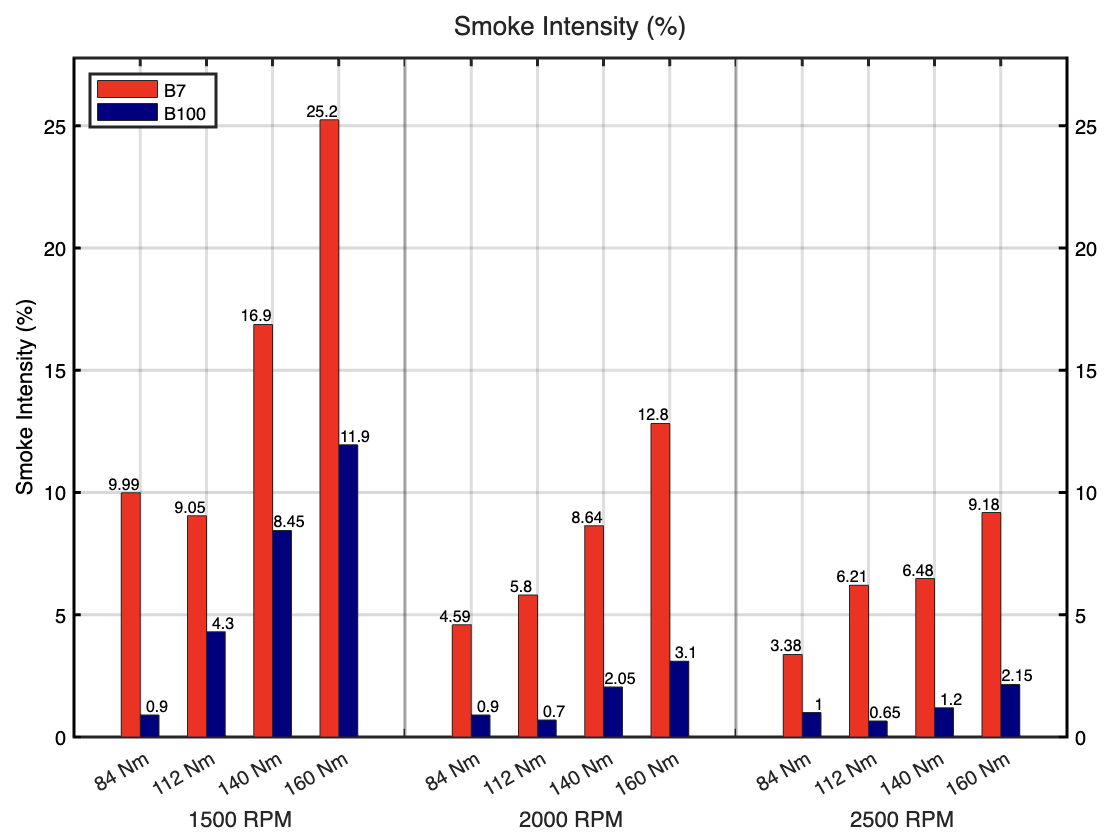

tile = ft_bar(EmiPMs, "Smoke Intensity (%)");